# 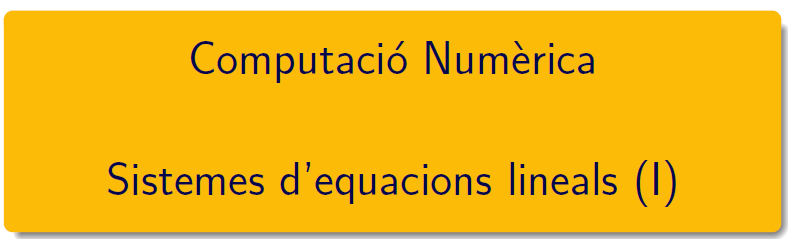

================================================================================

# TEMA 2 Àlgebra lineal numèrica (I)

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-CNLab2-3.pdf i en el document CN_full2.pdf, els podeu trobar en el campus virtual. 

## Mètodes directes

MATLAB implementa mètodes directes a través dels operadors de divisió de matrius [`/`](https://es.mathworks.com/help/matlab/ref/mrdivide.html) i [`\`](https://es.mathworks.com/help/matlab/ref/mldivide.html), així com funcions com [`decomposition`](https://es.mathworks.com/help/matlab/ref/decomposition.html), [`lsqminnorm`](https://es.mathworks.com/help/matlab/ref/lsqminnorm.html), and [`linsolve`](https://es.mathworks.com/help/matlab/ref/linsolve.html).

#### Factoritzacions en Matlab®

Consulteu [LU, Txoleski i QR](https://es.mathworks.com/help/matlab/math/factorizations.html)

Obtindre les diferents factoritzacions de la matriu A i resoleu després el sistema lineal Ax=b


$$A=\left( \begin{array}{rrrr}
16 & 4 & 0 & -4 \\
 4 & 5 & 2 & -1 \\
 0 & 2 & 2 & -2\\
-4 & -1 & -2 & 6
\end{array} \right)$$
    
$$b=\left(\begin{array}{r}   8\\ -2\\-4\\ 3\end{array} \right)$$


format shortG
A = [16 4 0 -4; 4 5 2 -1; 0 2 2 -2; -4 -1 -2 6]; b = [8; -2; -4;3];
[L,U,P] = lu(A)

L =             1            0            0            0
         0.25            1            0            0
        -0.25            0            1            0
            0          0.5         -0.5            1


U =            16            4            0           -4
            0            4            2            0
            0            0           -2            5
            0            0            0          0.5


P =      1     0     0     0
     0     1     0     0
     0     0     0     1
     0     0     1     0


% comprovem PA = LU
norm(P*A-L*U,1)

ans =      0


% la solució del sistema és en dos etapes, primer resolem Ly=Pb i després Ux=y
y = linsolve(L,P*b); linsolve(U,y)  % linsolve més eficient

ans =      1
    -1
     0
     1


% també pot ser
U\(L\P*b)

ans =      1
    -1
     0
     1


Factorització de Txoleski

% iflag = 0, indica simètrica definida positiva
[R,iflag] = chol(A); iflag

iflag =      0


% comprovem R'R = A
norm(R'*R-A,1)

ans =      0


% la solució del sistema és en dos etapes, primer resolem R'y=b i després Rx=y
R\(R'\b)

ans =      1
    -1
     0
     1


Factorització QR

[Q,R] = qr(A);
% comprovem A = QR
prova = norm(A-Q*R,1)

prova =    6.2172e-15


% la solució del sisema és Rx = Q'b (és la millor però es costosa)
% Ax = b -> QRx = b -> Q'QRx = Q'b -> Rx = 'Qb
linsolve(R,Q'*b)

ans =             1
           -1
   6.5842e-16
            1


#### Practiquem el·liminació gaussiana, LU, Txoleski, QR.

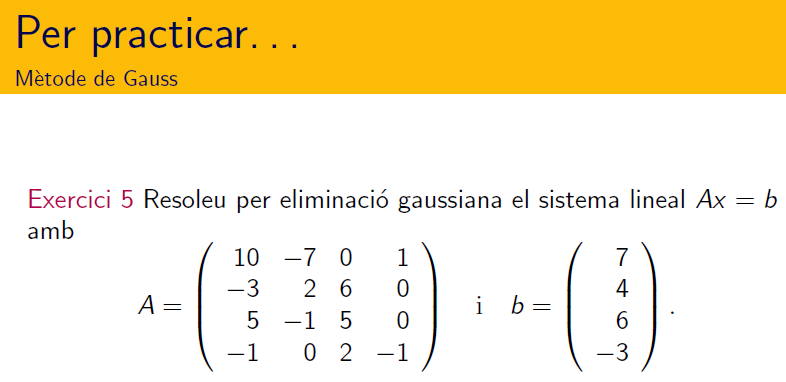

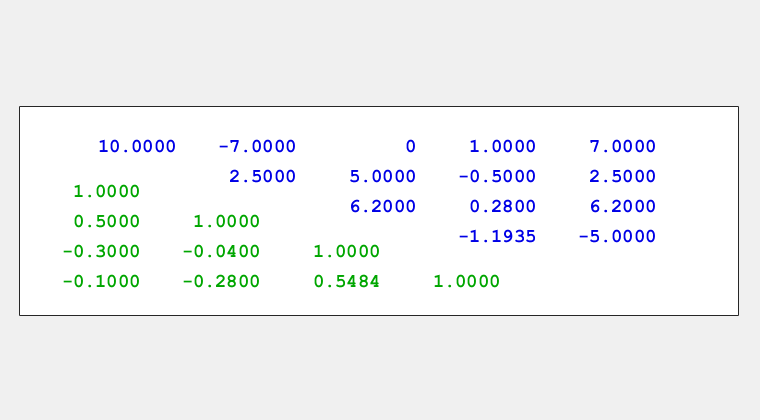

A = [10 -7 0 1; -3 2 6 0; 5 -1 5 0; -1 0 2 -1]; b = [7 4 6 -3]';
AM = [A,b];
% Funció de Cleve Moler, llibre Numerical Computing with Matlab
[L,U,pv,qv] = lugui(AM);

% Solució del sistema
Pb = AM(pv,qv); Pb = Pb(:,end);
% 1) Ly=Pb
y = linsolve(L,Pb)

y =             7
          2.5
          6.2
           -5


% 2) Ux=y 
x = linsolve(U(:,1:end-1),y)

x =       0.43243
      0.21622
      0.81081
       4.1892


% verifiquem la solució
r = b-A*x, rn = norm(r)

r =             0
   8.8818e-16
  -8.8818e-16
            0


rn =    1.2561e-15


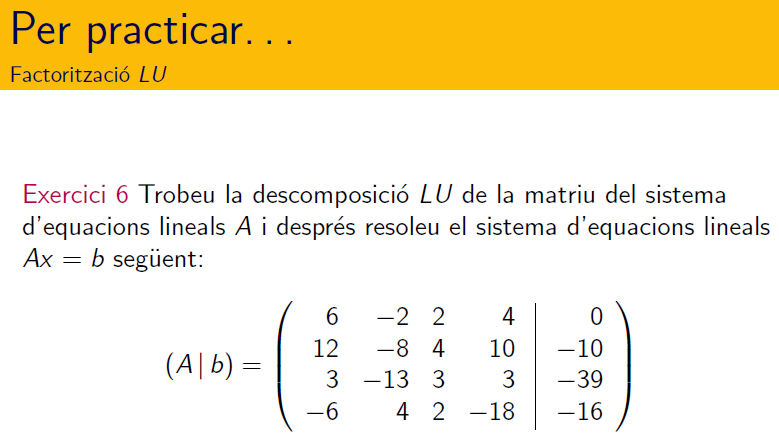

A = [6 -2 2 4; 12 -8 4 10; 3 -13 3 3; -6 4 2 -18]; b = [0 -10 -39 -16]';
[L,U,P] = lu(A);
% La resolució és en dos etapes, primer Ly=Pb, segon Ux=y
y = linsolve(L,P*b); x = linsolve(U,y)

x =             1
            3
           -2
            1


% verifiquem solució
r = b-A*x, rn = norm(r)

r =    8.8818e-16
   3.5527e-15
            0
            0


rn =    3.6621e-15


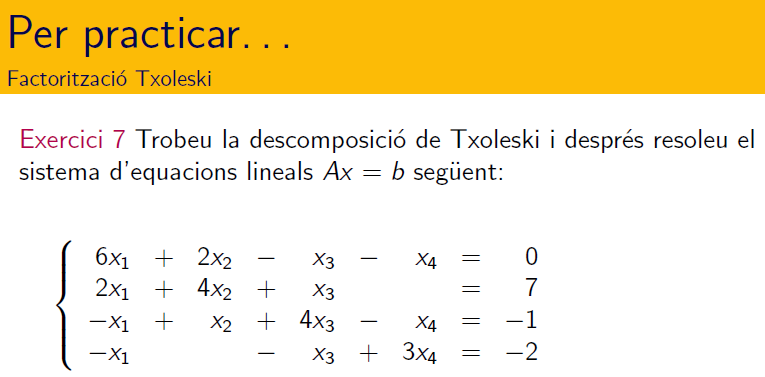

format short
A = [6 2 -1 -1; 2 4 1 0; -1 1 4 -1; -1 0 -1 3]; b = [0 7 -1 -2]';
% verifiquem simetria iflag = 0
[R,iflag] = chol(A); iflag

iflag = 0

% comprovem R'R = A
R'*R-A

ans = 	1.0e+-15 *

   -0.8882         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0    0.4441


% la solució del sistema és en dos etapes, primer resolem R'y=b i després Rx=y
% x = R\(R'\b)
y = linsolve(R',b);
x = linsolve(R ,y)

x =    -1.6291
    3.0331
   -1.8742
   -1.8344


% verifiquem solució
r = b-A*x, rn = norm(r)

r = 	1.0e+-14 *

    0.3553
   -0.0888
    0.0666
         0


rn = 3.7221e-15

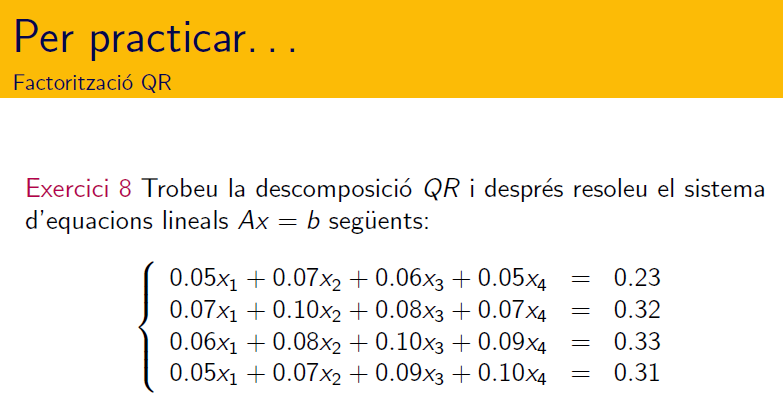

A = [5 7 6 5; 7 10 8 7; 6 8 10 9; 5 7 9 10]/100; b = [23 32 33 31]'/100;
[Q,R] = qr(A);
% comprovem A=QR    
A - Q*R

ans = 	1.0e+-16 *

    0.0694         0         0    0.2082
         0         0         0   -0.2776
         0         0         0    0.1388
         0         0         0    0.1388


% La solucuió del sistema és Rx=Q'b
x = linsolve(R,Q'*b)

x =     1.0000
    1.0000
    1.0000
    1.0000


% verifiquem la solució
r = b-A*x, rn = norm(r)

r = 	1.0e+-15 *

    0.0278
    0.1110
    0.0555
    0.0555


rn = 1.3878e-16

#### Nombre de condició d'una matriu (pàg 17, bloc 0)

Càlcul del nombre de condició d'una matriu en Matlab®: consulteu [Condition number of matrix](https://es.mathworks.com/help/symbolic/cond.html)

format longG
H = hilb(4)
condN2 = cond(H), condN1 = cond(H,1), condNf = cond(H,'fro'), condNi = cond(H,inf)

#### Vector residu i nombre de condició


$$\left (A|b\right ) = \left (
		\begin{array}{cccc|c}
		10 & 7 & 8 & 7 & 32\\
		 7 & 5 & 6 & 5 & 23\\
		 8 & 6 & 10 & 9 & 33\\
		 7 & 5 & 9 & 10 & 31\\
		\end{array}
		\right ) \stackrel{sol. exacte}{\longrightarrow}
		\left(
		\begin{array}{c}
		1 \\
		1 \\
		1 \\
    	1 \\
		\end{array}
		\right)$$
      
$$\left (A|b\right ) = \left (
\begin{array}{cccc|c}
10 & 7 & 8 & 7 & 32.1\\
7 & 5 & 6 & 5 & 22.9\\
8 & 6 & 10 & 9 & 33.1\\
7 & 5 & 9 & 10 & 30.9\\
\end{array}
\right ) \stackrel{sol. exacte}{\longrightarrow}
\left(
\begin{array}{c}
? \\
? \\
? \\
? \\
\end{array}
\right)$$


A = [10 7 8 7; 7 5 6 5; 8 6 10 9; 7 5 9 10];
format shortG
% Sistema lineal 
b1 = [32; 23; 33; 31];
b2 = [32.1; 22.9; 33.1; 30.9];
B = [b1,b2], x = A\B

B =            32         32.1
           23         22.9
           33         33.1
           31         30.9


x =             1          9.2
            1        -12.6
            1          4.5
            1         -1.1


% cond (mesura el mal condicionament), rcond (mesura el bon condicionament 1...0)
fprintf('paràmetres de condicionament\n'),K = cond(A,1), RK = rcond(A)

paràmetres de condicionament


K =          4488


RK =    0.00022282


% aixo pasa perque els errors es propaguen
fprintf('vector residu\n'),rx = A*x-B

vector residu


rx =             0  -1.4211e-14
            0  -7.1054e-15
            0  -7.1054e-15
            0  -1.0658e-14


prediccio = K*norm(b1-b2,1)/norm(b1,1)*100

prediccio =        1508.6


valor = norm(x(:,1)-x(:,2),1)/norm(x(:,1),1)*100

valor =           685


#### Fites error

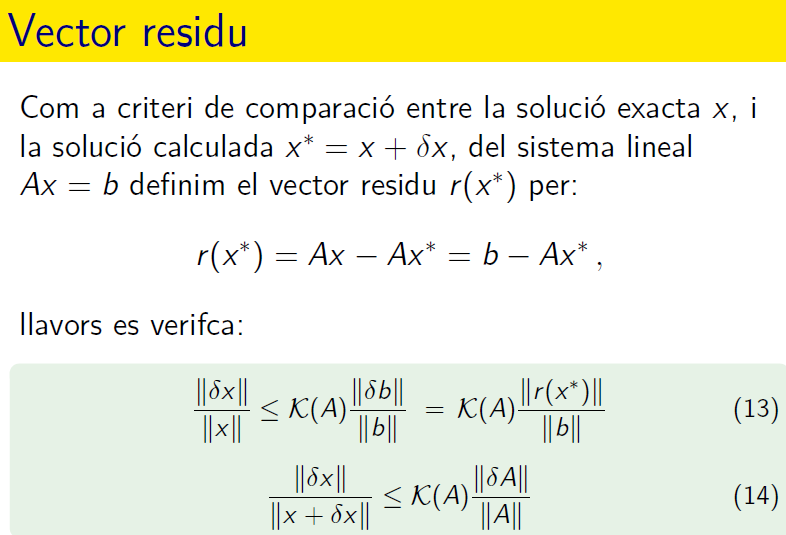

El nombre de condició d'una matriu apareix en les fites de l'error relatiu del resultat. Aquestes fites les podeu trobar en el llibre de la bibliografia Càlcul Numèric, Grau, M. i Noguera, M.

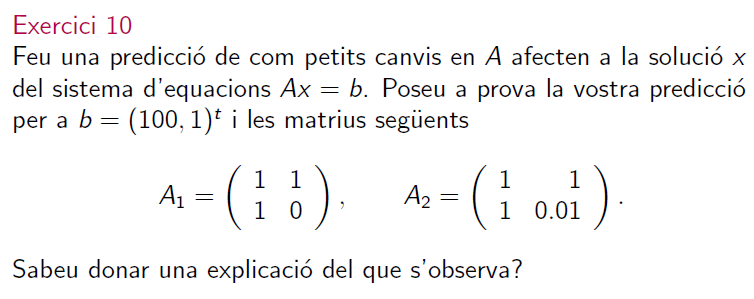

A1 = [1 1; 1 0]; A2 = [1 1; 1 0.01];
c1 = [cond(A1,1), cond(A1,2), cond(A1,'inf')]

c1 =             4        2.618            4


c2 = [cond(A2,1), cond(A2,2), cond(A2,'inf')]

c2 =        4.0404       2.6536       4.0404


b = [100 1]';
x1 = linsolve(A1,b)

x1 =      1
    99


x2 = linsolve(A2,b)

x2 =      0
   100


norm(x1-x2,1)/norm(x1,1)*100

ans =      2


K = cond(A1,1), K2 = cond(A2,1)

K =      4


K2 =        4.0404


prediccio = K*norm(A1-A2,1)/norm(A1,1)*100

prediccio =      2


% solució pot tenir estimació teòrica d'error d'uns 2